# **左手材料的负折射特性演示**

**        负折射率媒质也称为双负电磁参数媒质，即**$$$\varepsilon<0,\mu<0$$$**。反射角、折射角与入射角的关系如下**


$$$$\theta_{{r}}=\theta_{{i}}$$$$



$$$$\frac{\sin\theta_{t}}{\sin\theta_{i}}=\frac{k_{1}}{k_{2}}=-\frac{n_{1}}{\mid n_{2}\mid}$$$$


**        该种情况下的折射角 **$$$\theta_{t}<0$$$**，即折射线与入射线位居于法线同侧，故称为负折射现象。利用负折射可以实现介质平板的超透镜成像等。**

## **一、垂直极化波入射的负折射演示**

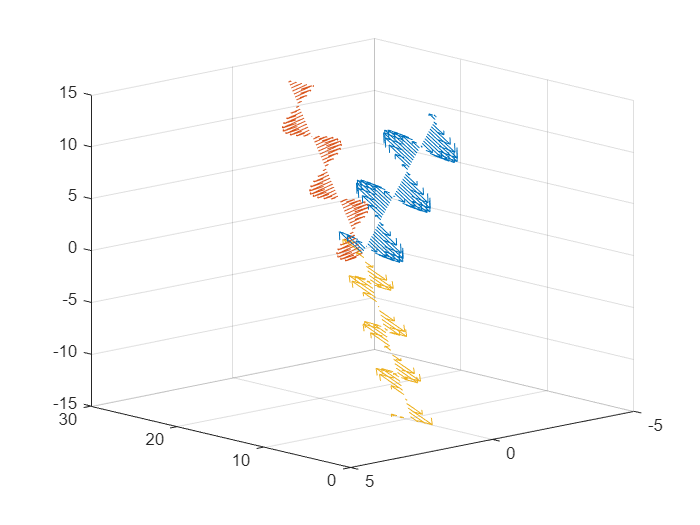

clc
clear
omega=3e8;              	%设置角频率
c=3e8;                     	%光速
k0=omega/c;                 %真空中的波数
E0=4;	                    %电场强度幅度
epsilonr1=1;                	%介质1的相对介电常数;
u1=1;                           %介质1的相对磁导率;
epsilonr2=-2;                	%介质2的相对介电常数;
u2=-1;                          %介质2的相对磁导率;
n1=sqrt(epsilonr1*u1);	        %介质1的折射率
n2=-sqrt(epsilonr2*u2);	        %介质2的折射率 介质2的折射率为负
thetai=pi/6;                	%入射角
thetar=thetai;              	%反射角
thetat=asin(n1/n2*sin(thetai));     	%透射角
k1=k0*n1;	%介质1的波数
k2=k0*n2;                   	%介质2的波数
gama=(u2*n1*cos(thetai)-u1*n2*cos(thetat))/(u2*n1*cos(thetai)+u1*n2*cos(thetat));
    	%反射系数计算公式
trans=2*u2*n1*cos(thetai)/(u2*n1*cos(thetai)+u1*n2*cos(thetat));
    	%透射系数计算公式
dm=15;
a=k0*dm/100;    	%空间步长
dt=a/c/n2;	%时间步长
x1=(0:a:k0*dm); 	%入射路径x坐标
z1=(k0*dm:-a:0)*cot(thetai);    	%入射路径z坐标
x2=(k0*dm:a:k0*dm*2);   	%反射路径x坐标
z2=(0:a:k0*dm)*cot(thetar); 	%反射路径z坐标
x3=(k0*dm:-a:0);   	%透射路径x坐标
z3=(0:a:k0*dm)*cot(thetat);   	%透射路径z坐标
Eix=zeros(size(x1));    	%以下语句初始化电场
Eiz=zeros(size(x1));    
Erx=zeros(size(x1));
Erz=zeros(size(x1));
Etx=zeros(size(x1));
Etz=zeros(size(x1));
l=zeros(size(x1));  	%设置一个零向量
t=0;    	%设置初始时间
for i=1:220
    if i<=101	%波尚未入射到界面
        Eix(1:i)=E0*cos(thetai)*cos(omega*t-(k1*sin(thetai)*x1(1:i)-k1*cos(thetai)*z1(1:i)));
        Eiz(1:i)=E0*sin(thetai)*cos(omega*t-(k1*sin(thetai)*x1(1:i)-k1*cos(thetai)*z1(1:i)));
        quiver3(x1,l,z1,Eix,l,Eiz,0);	%计算并绘制入射电场
    end
    if i>101
        Eix=E0*cos(thetai)*cos (omega*t-(k1*sin(thetai)*x1-k1*cos(thetai)*z1));
        Eiz=E0*sin(thetai)*cos (omega*t-(k1*sin(thetai)*x1-k1*cos(thetai)*z1));
	%波入射到界面，计算入射电场
        if i<=202	%波入射到界面，以下计算反射、透射电场
            Erx(1:i-101)=-E0*gama*cos(thetar)*cos(omega*t-(k1*sin(thetar)*x2(1:i-101)+k1*cos(thetar)*z2(1:i-101)));
            Erz(1:i-101)=E0*gama*sin(thetar)*cos(omega*t-(k1*sin(thetar)*x2(1:i-101)+k1*cos(thetar)*z2(1:i-101)));
            Etx(1:i-101)=E0*trans*cos(thetat)*cos(omega*t-(k2*sin(thetat)*x3(1:i-101)-k2*cos(thetat)*z3(1:i-101)));
            Etz(1:i-101)=-E0*trans*sin(thetat)*cos(omega*t-(k2*sin(thetat)*x3(1:i-101)-k2*cos(thetat)*z3(1:i-101)));
        end
        if i>202	%波传出研究区域，计算电场
            Erx=-E0*gama*cos(thetar)*cos(omega*t-(k1*sin(thetar)*x2+k1*cos(thetar)*z2));
            Erz=E0*gama*sin(thetar)*cos(omega*t-(k1*sin(thetar)*x2+k1*cos(thetar)*z2));
            Etx=E0*trans*cos(thetat)*cos(omega*t-(k2*sin(thetat)*x3-k2*cos(thetat)*z3));
            Etz=-E0*trans*sin(thetat)*cos(omega*t-(k2*sin(thetat)*x3-k2*cos(thetat)*z3));
        end
        quiver3(x1,l,z1,Eix,l,Eiz,0);	%绘制入射场
        hold on
        quiver3(x2,l,z2,Erx,l,Erz,1);	%绘制反射场
        hold on
        quiver3(x3,l,z3,Etx,l,Etz,0);	%绘制透射场
    end
axis([0,k0*dm*2,-k0*dm/3,k0*dm/3,-k0*dm,k0*dm]); view(k0/2*dm+i,k0*dm);     
	%设置显示范围和视角
    mov(i)=getframe(gcf);	%获取动画帧
    pause(0.01);	%暂停
    t=t+dt;	%时间步进
    hold off
end

- **动态展示**

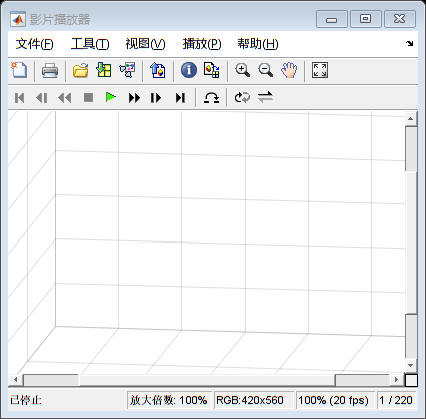

implay(mov);

- **保存为视频文件**

v=VideoWriter('垂直极化波.avi','Motion JPEG AVI');    %和前面的循环配合，实现动画输出为avi文件
open(v)
writeVideo(v,mov)
close(v)

## **二、平行极化波入射的负折射演示**

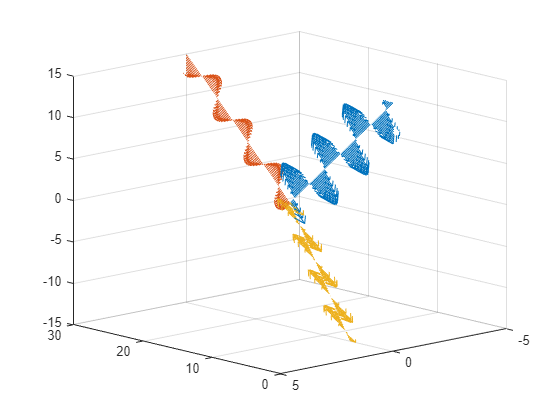

clc
clear
omega=3e8;              	%设置角频率
c=3e8; 	%光速
k0=omega/c;                     	%真空中的波数
E0=4;	%电场强度幅度
epsilonr1=1;                	%介质1的相对介电常数
u1=1;
epsilonr2=-2;                	%介质2的相对介电常数
u2=-1;
n1=sqrt(epsilonr1*u1);	%介质1的折射率
n2=-sqrt(epsilonr2*u2);	%介质2的折射率 介质2的折射率为负
thetai=pi/4;                	%入射角
thetar=thetai;              	%反射角
thetat=asin(n1/n2*sin(thetai));     	%透射角
k1=k0*n1;	%介质1的波数
k2=k0*n2;                   	%介质2的波数
gama=(u1*n2*cos(thetai)-u2*n1*cos(thetat))/(u1*n2*cos(thetai)+u2*n1*cos(thetat));
    	%反射系数计算公式
trans=2*u2*n1*cos(thetai)/(u1*n2*cos(thetai)+u2*n1*cos(thetat));
    	%透射系数计算公式
dm=15;
a=k0*dm/100;    	%空间步长
dt=a/c/n2;	%时间步长
x1=(0:a:k0*dm); 	%入射路径x坐标
z1=(k0*dm:-a:0)*cot(thetai);    	%入射路径z坐标
x2=(k0*dm:a:k0*dm*2);   	%反射路径x坐标
z2=(0:a:k0*dm)*cot(thetar); 	%反射路径z坐标
x3=(k0*dm:-a:0);   	%透射路径x坐标
z3=(0:a:k0*dm)*cot(thetat);   	%透射路径z坐标
Eix=zeros(size(x1));    	%以下语句初始化电场
Eiz=zeros(size(x1));    
Erx=zeros(size(x1));
Erz=zeros(size(x1));
Etx=zeros(size(x1));
Etz=zeros(size(x1));
l=zeros(size(x1));  	%设置一个零向量
t=0;    	%设置初始时间
for i=1:220
    if i<=101	%波尚未入射到界面
        Eix(1:i)=E0*cos(thetai)*cos(omega*t-(k1*sin(thetai)*x1(1:i)-k1*cos(thetai)*z1(1:i)));
        Eiz(1:i)=E0*sin(thetai)*cos(omega*t-(k1*sin(thetai)*x1(1:i)-k1*cos(thetai)*z1(1:i)));
        quiver3(x1,l,z1,Eix,l,Eiz,0);	%计算并绘制入射电场
    end
    if i>101
        Eix=E0*cos(thetai)*cos (omega*t-(k1*sin(thetai)*x1-k1*cos(thetai)*z1));
        Eiz=E0*sin(thetai)*cos (omega*t-(k1*sin(thetai)*x1-k1*cos(thetai)*z1));
	%波入射到界面，计算入射电场
        if i<=202	%波入射到界面，以下计算反射、透射电场
            Erx(1:i-101)=-E0*gama*cos(thetar)*cos(omega*t-(k1*sin(thetar)*x2(1:i-101)+k1*cos(thetar)*z2(1:i-101)));
            Erz(1:i-101)=E0*gama*sin(thetar)*cos(omega*t-(k1*sin(thetar)*x2(1:i-101)+k1*cos(thetar)*z2(1:i-101)));
            Etx(1:i-101)=E0*trans*cos(thetat)*cos(omega*t-(k2*sin(thetat)*x3(1:i-101)-k2*cos(thetat)*z3(1:i-101)));
            Etz(1:i-101)=-E0*trans*sin(thetat)*cos(omega*t-(k2*sin(thetat)*x3(1:i-101)-k2*cos(thetat)*z3(1:i-101)));
        end
        if i>202	%波传出研究区域，计算电场
            Erx=-E0*gama*cos(thetar)*cos(omega*t-(k1*sin(thetar)*x2+k1*cos(thetar)*z2));
            Erz=E0*gama*sin(thetar)*cos(omega*t-(k1*sin(thetar)*x2+k1*cos(thetar)*z2));
            Etx=E0*trans*cos(thetat)*cos(omega*t-(k2*sin(thetat)*x3-k2*cos(thetat)*z3));
            Etz=-E0*trans*sin(thetat)*cos(omega*t-(k2*sin(thetat)*x3-k2*cos(thetat)*z3));
        end
        quiver3(x1,l,z1,Eix,l,Eiz,0);	%绘制入射场
        hold on
        quiver3(x2,l,z2,Erx,l,Erz,1);	%绘制反射场
        hold on
        quiver3(x3,l,z3,Etx,l,Etz,0);	%绘制透射场
    end
    axis([0,k0*dm*2,-k0*dm/3,k0*dm/3,-k0*dm,k0*dm]); view(k0/2*dm+i,k0*dm);     
	%设置显示范围和视角
    mov(i)=getframe(gcf);	%获取动画帧
    pause(0.01);	%暂停
    t=t+dt;	%时间步进
    hold off
end

- **动态展示**

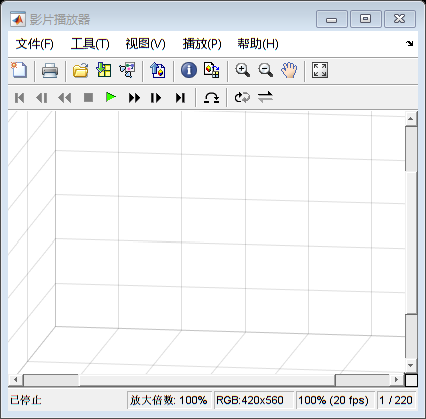

implay(mov);

- **保存为视频文件**

v=VideoWriter('平行极化波.avi','Motion JPEG AVI');    %和前面的循环配合，实现动画输出为avi文件
open(v)
writeVideo(v,mov)
close(v)